
%{
ES115 Drug Concentration in the Body
 originally from Module 2 Project Bank - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-25


State the problem (Purpose):
 Electric bill costs are compared based on usage values to determine which bill would be most cost effective.

Describe input values (Knowns)and required output (Unknowns) 
    Input: - Linear and Piecewise function
          - usage range
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}

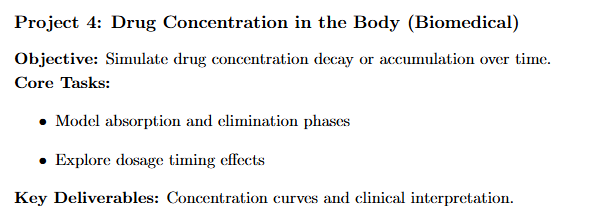


clear; clc; close all;    % Clear workspace

%user input system

dose = input("Enter dose amount in mg (e.g., 500): ");   %choose dosage amount (mg)
if isempty(dose)              % Default dose if choice left blank
    dose = 500;
end

a = input("Enter absorption rate constant a (e.g., 1.2): "); % choose Absorption rate
if isempty(a) % Default absorption rate if choice left blank
    a = 1.2;
end

e = input("Enter elimination rate constant e (e.g., 0.3): "); % choose Elimination rate
if isempty(e) % Default elimination rate if choice left blank
    e = 0.3;
end

int = input("Enter dosing interval in hours (e.g., 6): "); % Time between doses
if isempty(int) % Default interval if choice left blank
    int = 6;
end

doseN = input("Enter number of doses given (e.g., 4): ");  % choose # of doses total
if isempty(doseN)  %default # of doses
    doseN = 4;
end

ttime = input("Enter total simulation time in hours (e.g., 24): "); % choose Length of simulation
if isempty(ttime)  %default simulation length
    ttime = 24;
end

timestep = 0.01; % Time step (hours)
time = 0:timestep:ttime; %vector for time

%initial model creation 


Con = zeros(size(time));  % concentraion array
dosetimes = 0:int:(int*(doseN-1));  % # of times dose is distrubed 


%model absorption and elimination phases

% For each time point, compute absorption and elimination

for i = 2:length(time)     % Loop through each time point
    
    t = time(i); %Current time
    
    abs = 0;  % Initialize absorption at this time
    
    for d = 1:length(dosetimes) % Loop through every administered dose
        
        tDose = dosetimes(d);  % find dose timing
        
        if t >= tDose  % Only absorb after dose is taken
            
            abs = abs + dose * a * exp(-a * (t - tDose)); 
            % First-order absorption process  
        end
    end
    
    elimination = e * Con(i-1);  % First-order elimination based on current level
    
    dCtimestep = abs - elimination; % Net change in concentration
    
    Con(i) = Con(i-1) + dCtimestep * timestep;   % Numerical integration 
end

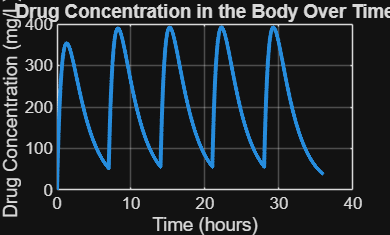

%plot results


figure;   %new figure window
plot(time, Con, 'LineWidth', 2);   % Plot concentration curve
xlabel("Time (hours)");% Label horizontal axis
ylabel("Drug Concentration (mg/L)"); % label vartical axis
title("Drug Concentration in the Body Over Time"); % title the plot
grid on; % Add grid for clarity

%display metric values


[maxConc, idx] = max(Con);  % Maximum drug concentration value
tMax = time(idx);   % Time in which maximum concentration occured

fprintf("\n=== PHARMACOKINETIC RESULTS ===\n"); % display heading


=== PHARMACOKINETIC RESULTS ===


fprintf("Peak Concentration: %.2f mg/L\n", maxConc); % Display peak concentration

Peak Concentration: 391.93 mg/L


fprintf("Time of Peak Concentration: %.2f hours\n", tMax); % Display time peak occurence

Time of Peak Concentration: 29.23 hours



steadyStateGuess = mean(Con(end-200:end));   % estimate approx steady state
fprintf("Approximate Steady-State Level: %.2f mg/L\n", steadyStateGuess); %display approx

Approximate Steady-State Level: 57.48 mg/L


%system thoughts and interpretations

fprintf("\n   CLINICAL INTERPRETATION   \n"); %display section title


=== CLINICAL INTERPRETATION ===



if maxConc > 50
    fprintf(" Peak concentration is high — risk of toxicity may be present. \n"); % if max concentration > 50 then concentration high
else
    fprintf(" Peak concentration is within a typical safe therapeutic range. \n"); % if max concentration <= 50 then concentration normal
end

Peak concentration is high — risk of toxicity may be present.



if steadyStateGuess < 5
    fprintf("Drug may be under-dosed; concentrations remain low.\n");  %if steady state < 5 then possible under dose
elseif steadyStateGuess > 40
    fprintf("Drug may accumulate excessively over repeated doses.\n");  %if steady state > 40 then possible over dose
else
    fprintf("Drug levels appear stable with repeated dosing.\n"); % if 5 <= steady state <= 40 then stable dose
end

Drug may accumulate excessively over repeated doses.



fprintf("Shorter dosing intervals will raise steady-state levels.\n");

Shorter dosing intervals will raise steady-state levels.


fprintf("Higher elimination rate e will reduce accumulation.\n");

Higher elimination rate ke will reduce accumulation.


fprintf("Higher absorption rate a causes faster onset of effect.\n");

Higher absorption rate ka causes faster onset of effect.


%{ 
Reflection After Completing the Project: 

- What did you learn?
 Throughout my completion of this project, ... 
 
  - What could be done differently?
many features among this project couldv'e been done differently such as ... 
   
- Rate the project (1 - 10) (1 - represents simple and 10 represents difficult) 
   Rate : ...
%}